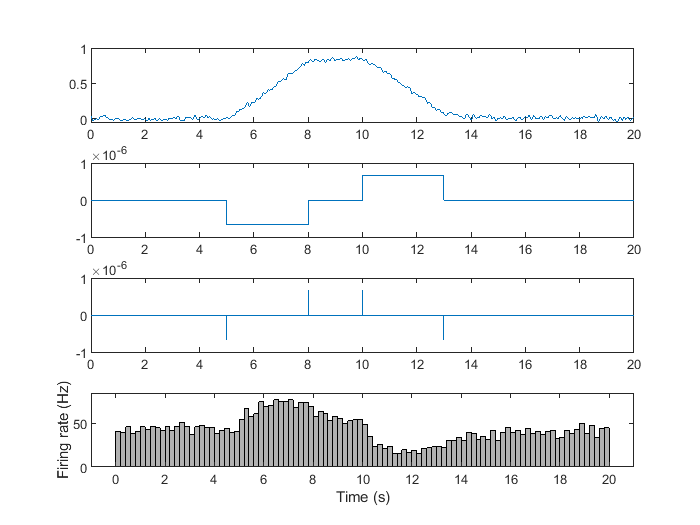

raster = P.raster;
sptimes = [];

for i=1:P.complete_trials
    sptimes = [sptimes find(raster(i,:)==1)];    
end

nbins = 100;
figure;

subplot(4,1,1); plot(P.time(1:P.single_trial_length),P.mean_movement);
subplot(4,1,2); plot(P.time(2:P.single_trial_length),diff(P.intendedStimulus(1,:)));
subplot(4,1,3); plot(P.time(3:P.single_trial_length),diff(P.intendedStimulus(1,:), 2));
subplot(4,1,4);
h = histogram(sptimes/P.fs, nbins);
h.FaceColor= 'k';
h.FaceAlpha = 0.3;
ax = gca;

mVal = max(h.Values) + round(max(h.Values)*0.1);
ax.YLim = [0 mVal];


stim_length = length(raster(1,:));
bin_duration = stim_length/nbins;
nbins_per_sec = 1000/bin_duration;

% for i=1:length(ax.YTickLabel)
%     label = str2num(ax.YTickLabel{i});
%     conv = (label/length(sptimes))*nbins_per_sec;
%     newLabel{i} = num2str(conv);
% end

% ax.YTickLabel = newLabel;
ax.YLabel.String = "Firing rate (Hz)";
ax.XLabel.String = "Time (s)";


% hold on;
% yyaxis right;
% plot(P.mean_movement);
